clc; clear ; close all;warning off;
cd 'D:\03_Battery\Model\Paper_Battery Parameter\Script\'
[file] = uigetfile('*.mat');
Dataset_File = load(file);

Error using load
Must be a text scalar.

segment_num = 11; % Dataset Split to N Segment to Estimate ECM Parameters
SOC_Plot_act = 0:(100/(segment_num-1)):100; %percent

Architecture = 0; %Select ECM Model
[Voltage,Current,Time,Param] = extract_para_Dataset_Sc(Dataset_File,Architecture,segment_num);

Nominal_Capacity = 2.5;%Ah  

VOC = Param.VOC;
R0 = Param.R0;
if (Architecture==1)
    R0 = cell2mat(Param.R0);
    R1 = cell2mat(Param.R1);
    C1 = cell2mat(Param.C1);
end

fittype = 'poly1';
method = fittype;
[V_Param] = createFit_Vol(Voltage,Time,method);
if (Architecture==0)
    [VOC_Param , R0_Param,VOC_SOC_para,R0_SOC_para] = createFit_Battery_Parameters(SOC_Plot_act,VOC,R0,method);
elseif (Architecture==1)
    [VOC_Param , R0_Param , R1_Param , C1_Param,VOC_SOC_para,R0_SOC_para,R1_SOC_para,C1_SOC_para] = createFit_Battery_Parameters_TimeCon(SOC_Plot_act,VOC,R0,R1,C1,method);
end

Static=Simulink.Variant('Architecture == 0');
Dynamic=Simulink.Variant('Architecture == 1');
sim('Final_ECM_SC.slx');

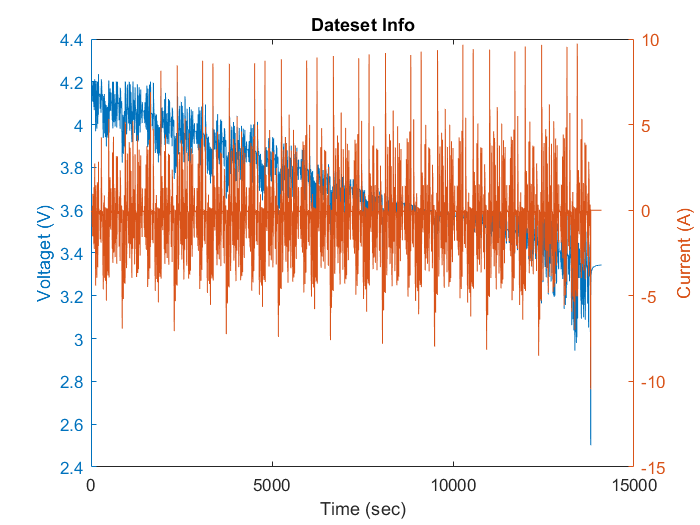

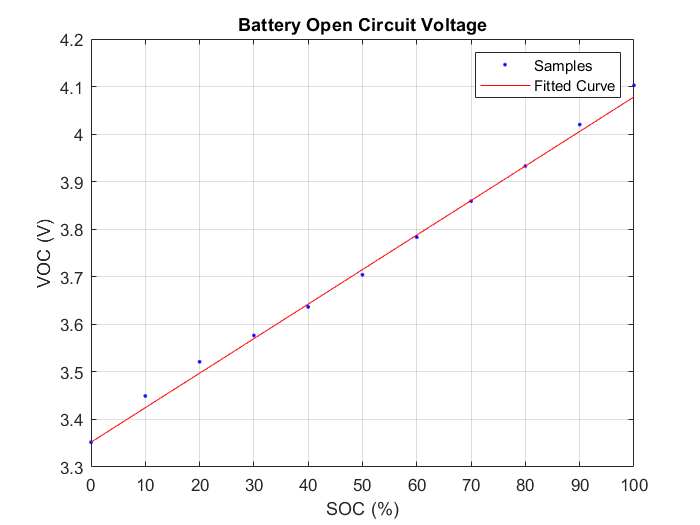

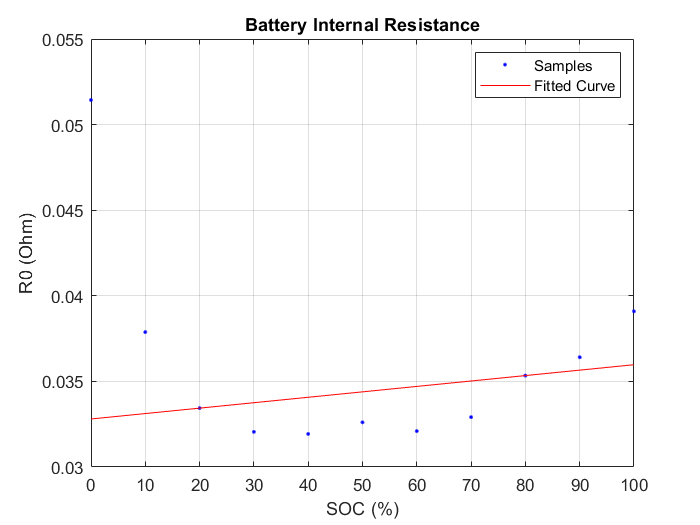

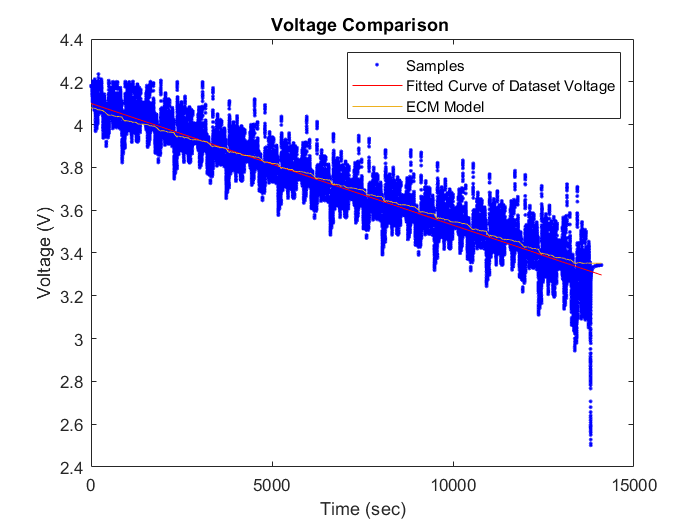

 figures;

open_system("Final_ECM_SC.slx") % Open the final model
save(Architecture + " _ECM Voltage_" +  fittype , "Calculated_Voltage");
clear all;